Jesus Molina Roldan

# SISTEMES d'EQUACIONS (SESSIÓ 8)

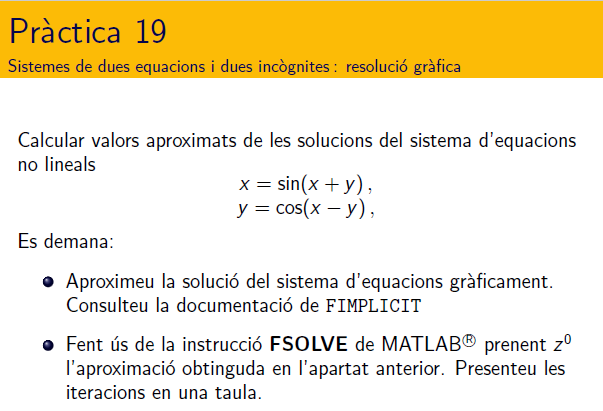

#### Resolució.

- Representeu en un mateix gràfic, les corbes $x-\sin(x+y)=0$ i $y-\cos(x-y)=0$ per a $x\in[-5,5]$ i per a $y\in[-5,5]$

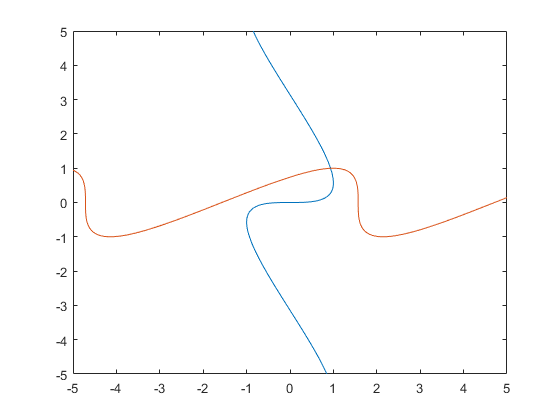

F1=@(x,y)x-sin(x+y);
F2=@(x,y)y-cos(x-y);
fimplicit({F1,F2})              

-  Canvieu el domini de les variables x i y a l'entorn del punt on es creuen les dues gràfiques

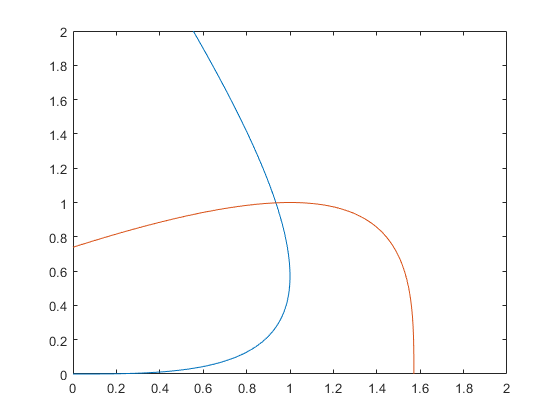

fimplicit({F1,F2},[ 0, 2 ,0 , 2])   

-  Calcular el punt on es creuen les dues gràfiques amb **FSOLVE** de Matlab. Per això cal definir el sistema d'equacions en una funció. (vegeu al final del document)

%doc fsolve
clearvars;
F = system([1,1]); disp(F')   % Valor de la funció que defineix el sistema d'equacions en [1;1]

     0.090703
            0



options = optimoptions('fsolve','Display','iter');
z0 = [1;1]; 
[x,fval] = fsolve(@system,z0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00822696                         0.128               1
     1          6     7.74869e-06      0.0640488        0.00285               1
     2          9      1.4696e-11     0.00216057       5.09e-06               1
     3         12     3.04197e-23    2.70288e-06       6.97e-12               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem a

x =       0.93508
      0.99802


fval =    5.2274e-12    1.759e-12


# SISTEMES d'EQUACIONS (SESSIÓ 8)

## 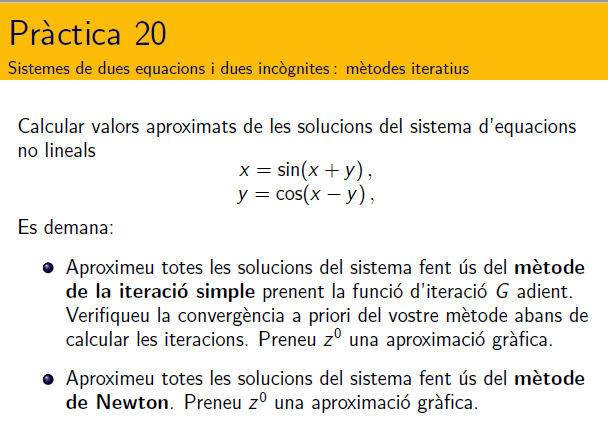

## Método del punto fijo

**Método del punto fijo con control del error y del número de iteraciones**

Matriz jacobiana de la función d'iteración calculada en Symbolic Math Toolbox

%%---SymbolicMathToolbox------------------------------------------------------------
syms x y
G(x,y)=[sin(x+y); cos(x-y)]                % Función de iteración

$$G(x, y) = \left(\begin{array}{c} \sin\left(x+y\right)\\ \cos\left(x-y\right) \end{array}\right)$$

JG(x,y)=jacobian(G(x,y),[x,y])             % Matriz jacobiana de la función de iteración

$$JG(x, y) = \left(\begin{array}{cc} \cos\left(x+y\right) & \cos\left(x+y\right)\\ -\sin\left(x-y\right) & \sin\left(x-y\right) \end{array}\right)$$

Z0=[1;1]

Z0 =      1
     1


control=JG(Z0(1),Z0(2)); 
control2=norm(control,1); 
criteriTEOREMA=vpa(control2,8)

$$criteriTEOREMA = 0.41614684$$

%%----Aritmética de punto flotante------------------------------------------------------
clear x y G(x,y) JG(x,y)
if criteriTEOREMA >=1 
    error('método divergente')
else
    disp('método convergente')
    G=@(x,y)[sin(x+y); cos(x-y)];
    F=@(x,y)[x-sin(x+y); y-cos(x-y)];
    alpha = metodo_punto_fijo(G,F,Z0,11,0.5*10^(-7));
end

método convergente



solución = 0.93508     0.99802
tolF = 1.8619e-08
tolZ = 9.0896e-08
iteraciones = 11



## Método de Newton

Criterio con control del error y del número de iteraciones

clearvars; format short g;

Z0=[1;1]  

Z0 =      1
     1


F=@(x,y)[x-sin(x+y); y-cos(x-y)]; F(Z0(1),Z0(2))

ans =      0.090703
            0


DF=@(x,y)[1-cos(x+y), -cos(x+y); sin(x-y), 1-sin(x-y)]; DF(Z0(1),Z0(2))

ans =        1.4161      0.41615
            0            1


tolZ=0.5*10^(-7);
tolF= 0.5*10^(-7); 
Nmax=10;
alpha = newton(F,DF,Z0,Nmax,tolF,tolZ); 


solución = 0.93508     0.99802
tolF = 0
tolZ = 3.8295e-12
iteraciones = 4



# SISTEMES d'EQUACIONS (SESSIÓ 8)

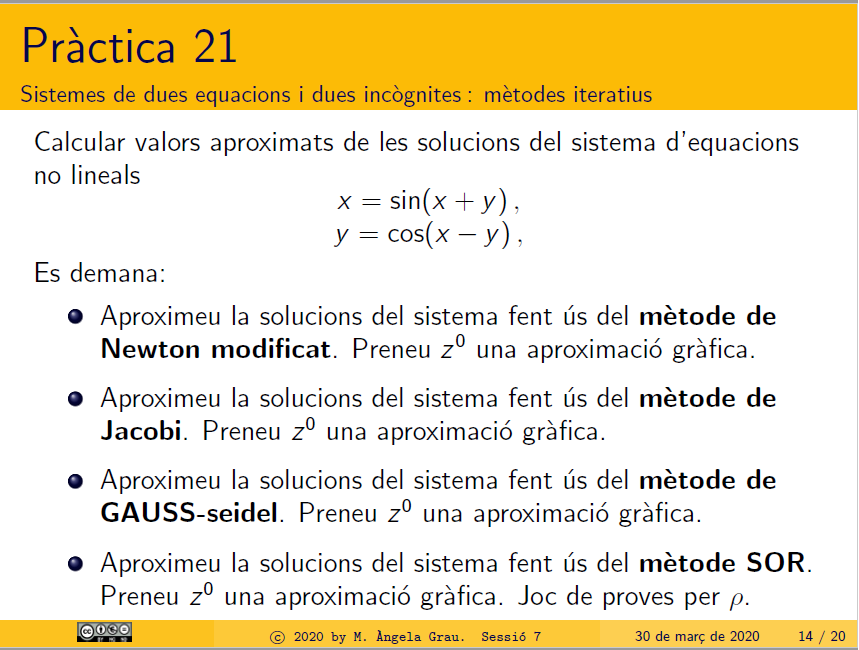

Z0=[1;0.9];
F=@(x,y)[x-sin(x+y); y-cos(x-y)]; F(Z0(1),Z0(2));
DF=@(x,y)[1-cos(x+y), -cos(x+y); sin(x-y), 1-sin(x-y)]; DF(Z0(1),Z0(2));
tolZ=0.5*10^(-7);
tolF= 0.5*10^(-7); 
Nmax=10;
alpha = newton_newtonmodificat(F,DF,Z0,Nmax,tolF,tolZ);


solución = 0.93508     0.99802
tolF = 1.5326e-08
tolZ = 8.2021e-08
iteraciones = 10




alpha = newton_metodejacobi(F,DF,Z0,Nmax,tolF,tolZ);


solución = 0.93508     0.99802
tolF = 1.7596e-09
tolZ = 7.2359e-09
iteraciones = 9



alpha = newton_metodegauss_seidel(F,DF,Z0,Nmax,tolF,tolZ);


solución = 0.93508     0.99802
tolF = 4.3957e-10
tolZ = 2.0982e-08
iteraciones = 6



F=@(x,y)[x-sin(x+y); y-cos(x-y)]; F(Z0(1),Z0(2));
DF=@(x,y)[1-cos(x+y), -cos(x+y); sin(x-y), 1-sin(x-y)]; DF(Z0(1),Z0(2));
tolZ=0.5*10^(-7);
tolF= 0.5*10^(-7); 
rho = 0.25;
alpha = newton_metodoSOR(F,DF,Z0,Nmax,tolF,tolZ,rho);


solución = 0.93508     0.99802
tolF = 1.7631e-08
tolZ = 7.4437e-08
iteraciones = 10



# Exercici 5 - Full 5

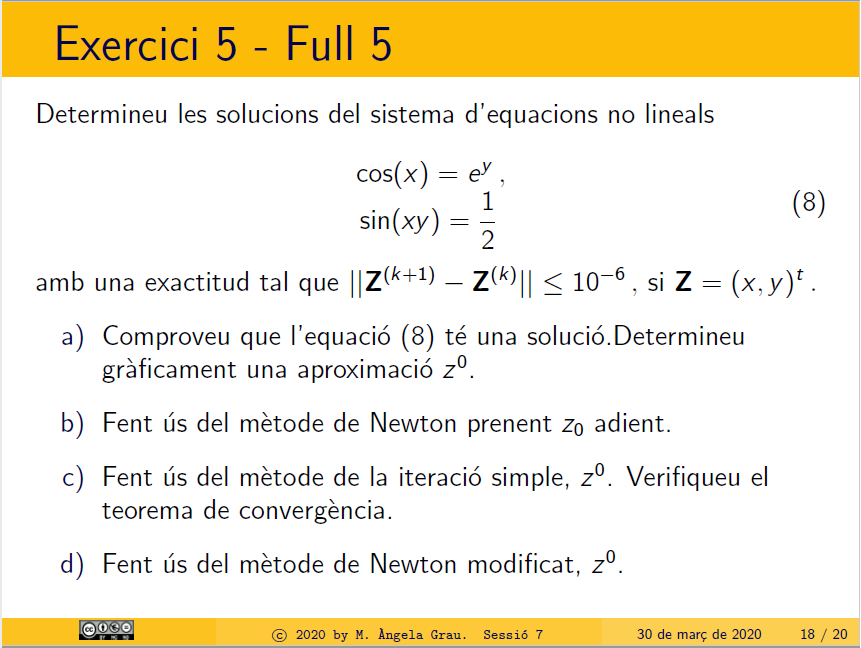

a) Com podem veure graficamente, té moltes solucions.

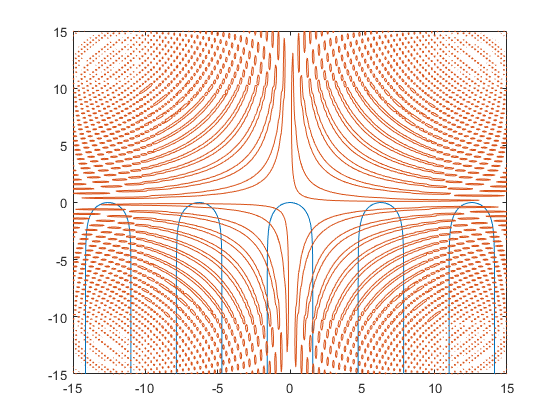

F1=@(x,y)cos(x)-exp(y);
F2=@(x,y)sin(x*y)-1/2;
fimplicit({F1,F2}, [-15,15,-15,15 ]) 

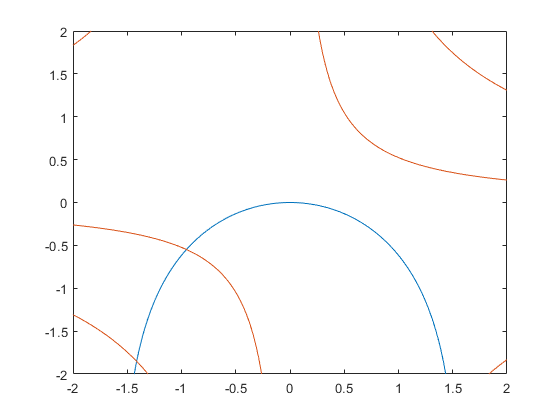

fimplicit({F1,F2}, [-2, 2, -2, 2]) 

%doc fsolve
clearvars;
F = system2([-1,-0.5]); disp(F');   % Valor de la funció que defineix el sistema d'equacions en [1;1]

    -0.066228
    -0.020574



options = optimoptions('fsolve','Display','iter');
z0 = [-1;-0.5]; 
[x,fval] = fsolve(@system2,z0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3       0.0048095                        0.0582               1
     1          6     5.26393e-06      0.0647685        0.00231               1
     2          9     3.25356e-12     0.00228247       1.69e-06               1
     3         12     2.51274e-24    1.75586e-06        1.6e-12               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem a

x =       -0.9547
     -0.54844


fval =   -8.8252e-13  -1.3168e-12


b)

Z0 = [-1;-0.5];
F=@(x,y)[cos(x)-exp(y); sin(x*y)-1/2]; F(Z0(1),Z0(2));
DF=@(x,y)[-sin(x), -exp(y); y*cos(x*y), x*cos(x*y)]; DF(Z0(1),Z0(2));
tolZ=0.5*10^(-7);
tolF= 0.5*10^(-7); 
Nmax=10;
alpha = newton(F,DF,Z0,Nmax,tolF,tolZ); 


solución = -0.9547    -0.54844
tolF = 5.5511e-17
tolZ = 1.5762e-12
iteraciones = 4



c)

control=DF(Z0(1),Z0(2));
control2=norm(control,1); 
criteriTEOREMA=vpa(control2,8)

$$criteriTEOREMA = 1.4841132$$

if criteriTEOREMA >=1 
    disp('método divergente')
else 
    disp('método convergente')
    G=@(x,y)[(exp(y)/cos(x))+x; (2*sin(x*y)+y)];
    G=@(x,y)[acos(exp(y)), asin(1/2)]
    alpha = metodo_punto_fijo(F,G,Z0,Nmax,tolF);
end

método divergente


d)

alpha = newton_newtonmodificat(F,DF,Z0,Nmax,tolF,tolZ);


solución = -0.9547    -0.54844
tolF = 7.6791e-10
tolZ = 1.4467e-08
iteraciones = 6



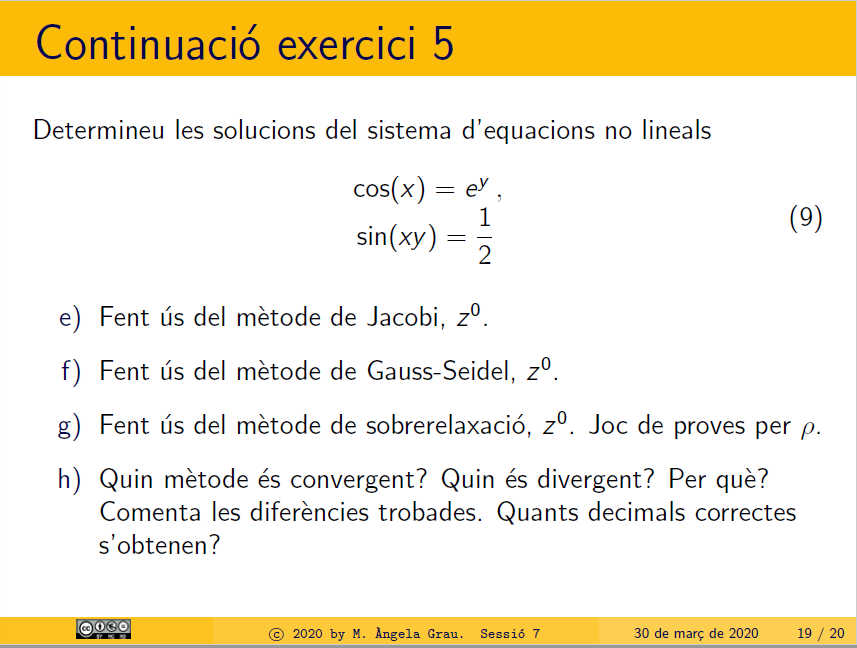

e)

alpha = newton_metodejacobi(F,DF,Z0,Nmax,tolF,tolZ);


solución = -0.95421    -0.54898
tolF = 0.000742
tolZ = 0.0013078
iteraciones = 10



f)

alpha = newton_metodegauss_seidel(F,DF,Z0,Nmax,tolF,tolZ);


solución = -0.95471    -0.54844
tolF = 1.0174e-05
tolZ = 3.535e-05
iteraciones = 10



g)

F=@(x,y)[x-sin(x+y); y-cos(x-y)]; F(Z0(1),Z0(2));
DF=@(x,y)[1-cos(x+y), -cos(x+y); sin(x-y), 1-sin(x-y)]; DF(Z0(1),Z0(2));
tolZ=0.5*10^(-7);
tolF= 0.5*10^(-7); 
rho = 0.25;
alpha = newton_metodoSOR(F,DF,Z0,Nmax,tolF,tolZ,rho);


solución = 0.0530267938156     -10089743.0937
tolF = 10089742.0939
tolZ = 26115028.4666
iteraciones = 10



h)

% Como podemos ver con el punto Z0 los unicos metodos que son divergentes
% son el metodo de punto fijo y el metodo de SOR. El metodo de punto fijo
% diverge porqu tolF es un numero distinto a la aproximacion a 0 y a parte
% la solucion es incorrecta.
% Los numero de dcimales correctos de cada metodo se puede determinar a
% partir de la cantidad de zeros que hay despues de la coma en la variable
% tolZ.
%Como podemos ver hay algunos metodos mejores que otros. Podriamos decir
%que el newton modificado es el mejor porque encuentra la solucion con
%menos iteraciones

function F=system(z)
    F(1) = z(1)-sin(z(1)+z(2));
    F(2) = z(2)-cos(z(1)-z(2));
end
function F=system2(z)
    F(1) = cos(z(1))-exp(z(2));
    F(2) = sin(z(1)*z(2))-1/2;
end

# Metodo punto fijo

function alpha = metodo_punto_fijo(G,F,Z,Nmax,tol)
    k=0; 
    tolZ=norm(Z);
    FZ=F(Z(1),Z(2)); 
    tolF= norm(FZ); 
    
    while (k<Nmax && (tolF>tol || tolZ>tol))
        Zold=Z;
        Z=G(Z(1),Z(2));
        tolF=norm(F(Z(1),Z(2)));
        tolZ=norm(Z-Zold);
        k=k+1;
    end
    alpha=Z;
    fprintf('\n')
    disp(['solución = ',num2str(Z')]);
    disp(['tolF = ',num2str(tolF)]);
    disp(['tolZ = ',num2str(tolZ)]);
    disp(['iteraciones = ',num2str(k)]);
    fprintf('\n')
end

# Metodo Newton

function alpha = newton(F,DF,Z,Nmax,tolF,tolZ)
% Mètode de Newton per a funcions de dues variables
    k=0; cotaF=1; cotaZ=1;
    FZ=F(Z(1),Z(2)); 
    DFZ=DF(Z(1),Z(2)); 
    while (k<Nmax && (cotaF>tolF || cotaZ>tolZ))
        Zold=Z;
        Y=DFZ\(-FZ);
        Z=Zold+Y;
        cotaZ=norm(Y);
        DFZ=DF(Z(1),Z(2));
        FZ=F(Z(1),Z(2));
        cotaF=norm(FZ);
        k=k+1;
    end
    alpha=Z;
    fprintf('\n')
    disp(['solución = ',num2str(Z')]);
    disp(['tolF = ',num2str(cotaF)]);
    disp(['tolZ = ',num2str(cotaZ)]);
    disp(['iteraciones = ',num2str(k)]);
    fprintf('\n')
end

# Variants del mètode de Newton

# Newton modificat

function alpha = newton_newtonmodificat(F,DF,Z,Nmax,tolF,tolZ)
% Mètode de Newton per a funcions de dues variables
    k=0; cotaF=1; cotaZ=1;
    FZ=F(Z(1),Z(2)); 
    DFZ=DF(Z(1),Z(2)); 
    while (k<Nmax && (cotaF>tolF || cotaZ>tolZ))
        Zold=Z;
        Y=DFZ\(-FZ);
        Z=Zold+Y;
        cotaZ=norm(Y);
        FZ=F(Z(1),Z(2));
        cotaF=norm(FZ);
        k=k+1;
    end
    alpha=Z;
    fprintf('\n')
    disp(['solución = ',num2str(Z')]);
    disp(['tolF = ',num2str(cotaF)]);
    disp(['tolZ = ',num2str(cotaZ)]);
    disp(['iteraciones = ',num2str(k)]);
    fprintf('\n')
end

# Metode de Jacobi

function alpha = newton_metodejacobi(F,DF,Z,Nmax,tolF,tolZ)
% Mètode de Newton per a funcions de dues variables
    k=0; cotaF=1; cotaZ=1;
    FZ=F(Z(1),Z(2)); 
    DFZ=DF(Z(1),Z(2)); 
    DFZ = diag(diag(DFZ));
    while (k<Nmax && (cotaF>tolF || cotaZ>tolZ))
        Zold=Z;
        Y=DFZ\(-FZ);
        Z=Zold+Y;
        cotaZ=norm(Y);
        DFZ=DF(Z(1),Z(2));
        DFZ = diag(diag(DFZ));
        FZ=F(Z(1),Z(2));
        cotaF=norm(FZ);
        k=k+1;
    end
    alpha=Z;
    fprintf('\n')
    disp(['solución = ',num2str(Z')]);
    disp(['tolF = ',num2str(cotaF)]);
    disp(['tolZ = ',num2str(cotaZ)]);
    disp(['iteraciones = ',num2str(k)]);
    fprintf('\n')
end

# Metode de Gauss Seidel

function alpha = newton_metodegauss_seidel(F,DF,Z,Nmax,tolF,tolZ)
% Mètode de Newton per a funcions de dues variables
    k=0; cotaF=1; cotaZ=1;
    FZ=F(Z(1),Z(2)); 
    DFZ=DF(Z(1),Z(2)); 
    DFZ = tril(DFZ);
    while (k<Nmax && (cotaF>tolF || cotaZ>tolZ))
        Zold=Z;
        Y=DFZ\(-FZ);
        Z=Zold+Y;
        cotaZ=norm(Y);
        DFZ=DF(Z(1),Z(2));
        DFZ = tril(DFZ);
        FZ=F(Z(1),Z(2));
        cotaF=norm(FZ);
        k=k+1;
    end
    alpha=Z;
    fprintf('\n')
    disp(['solución = ',num2str(Z')]);
    disp(['tolF = ',num2str(cotaF)]);
    disp(['tolZ = ',num2str(cotaZ)]);
    disp(['iteraciones = ',num2str(k)]);
    fprintf('\n')
end

# Metode de SOR

function alpha = newton_metodoSOR(F,DF,Z,Nmax,tolF,tolZ,rho)
% Mètode de Newton per a funcions de dues variables
    k=0; cotaF=1; cotaZ=1;
    FZ=F(Z(1),Z(2)); 
    DFZ=rho*diag(diag(DF(Z(1),Z(2)))) + tril(DF(Z(1),Z(2))); 
    while (k<Nmax && (cotaF>tolF || cotaZ>tolZ))
        Zold=Z;
        Y=DFZ\(-FZ);
        Z=Zold+Y;
        cotaZ=norm(Y);
        DFZ= rho*diag(diag(DF(Z(1),Z(2)))) + tril(DF(Z(1),Z(2)));
        FZ=F(Z(1),Z(2));
        cotaF=norm(FZ);
        k=k+1;
    end
    alpha=Z;
    fprintf('\n')
    disp(['solución = ',num2str(Z')]);
    disp(['tolF = ',num2str(cotaF)]);
    disp(['tolZ = ',num2str(cotaZ)]);
    disp(['iteraciones = ',num2str(k)]);
    fprintf('\n')
end